# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha: 25/11/2021**

clc;
clear all;
close all;

# Tema 4. Ejercicio 3 - Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de todos los objetos de una imagen y utilizar sólo las componentes más significativas de cada objeto para reconstruirlos.

Step 1) Read Image

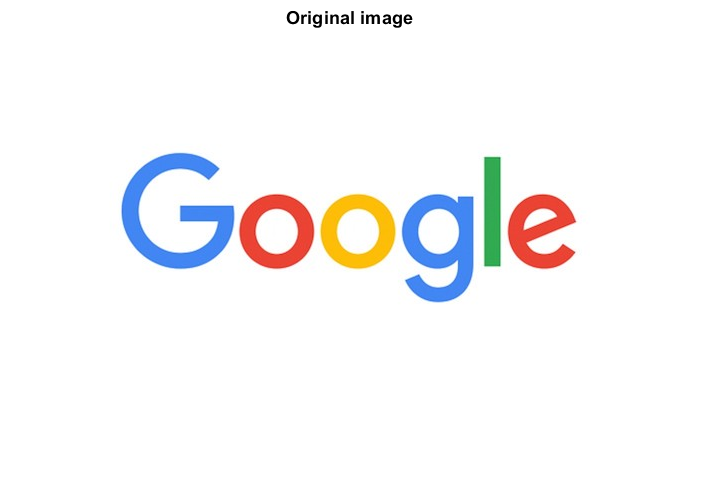

imgOriginal = imread('google.jpg');
figure;
imshow(imgOriginal);
title('Original image');

Step 2) Threshold the Image

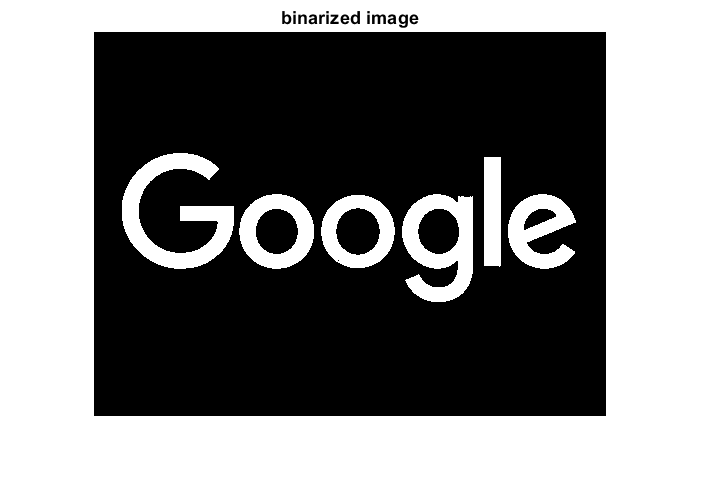

if size(imgOriginal,3) == 3
    imgOriginal = rgb2gray(imgOriginal);
end
imgBW = imbinarize(imgOriginal);
imgBW = imcomplement(imgBW);

figure;
imshow(imgBW);
title('binarized image');

Step 4) Find the external Boundaries

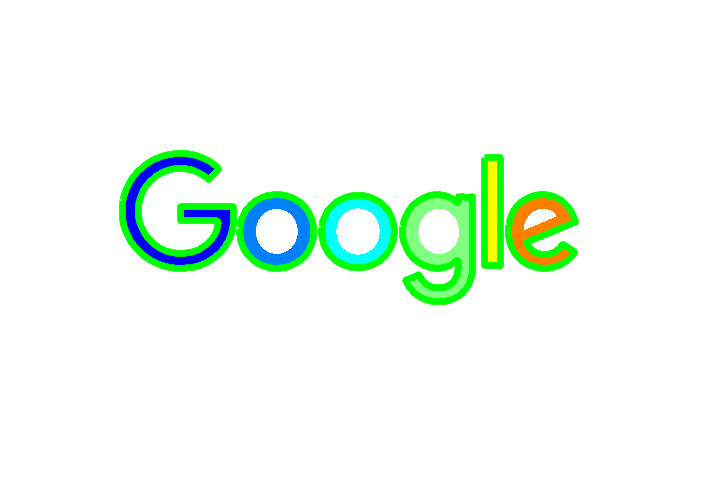

[B,L] = bwboundaries(imgBW,'noholes');
figure
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for k = 1:length(B)
    boundary = B{k};
    plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
end

Step 5)  Fourier transform 

for k = 1:length(B)
    boundary = B{k};
    % fourier_transform()    % a partir de las boundaries
    % proporciona la transformada de Fourier
    % (listado de números complejos)
    
    % fourier_inv_transform()   % a partir de un número determinado de componentes de
    % la transformada de Fourier recupera las boundaries aproximadas
    
    % plot recovered boundary
    
end

Se pide: 

- Complete el paso 5, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier de cada uno de los objetos etiquetados.

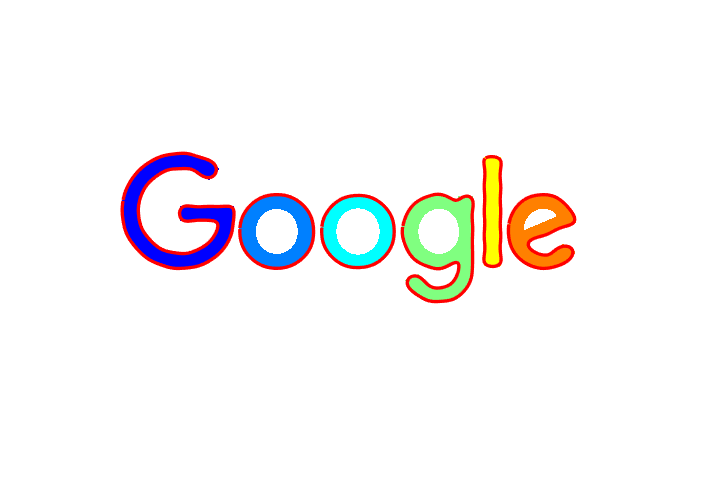

figure;
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for i = 1:length(B)
    boundary = B{i};
    z = fourier_transform(boundary);
    s = fourier_inv_transform(z, 8*length(z)/100);                                                    
    plot(s(:,2), s(:,1), 'r', 'LineWidth', 2);
end

**Tras varias pruebas hechas con la slidebar hemos determinado que al usar un 8% de los puntos del borde el contorno de cada componente .**

         2. Obtenga los contornos reconstruidos de los objetos etiquetados utilizando realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Utilice el 10% de las componentes para la reconstrucción y dibuje el contorno recuperado.

figure;
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for i = 1:length(B)
    boundary1 = B{i};
    z1 = fourier_transform(boundary1);
    perc1 = 10*length(z1)/100;
    length(z1)
    s1 = fourier_inv_transform(z1, perc1);                                                        
    plot(s1(:,2), s1(:,1), 'r', 'LineWidth', 2);
end

         3. Reduzca el número de componentes utilizados para la reconstrucción a 5% y 2% y explique sus conclusiones.

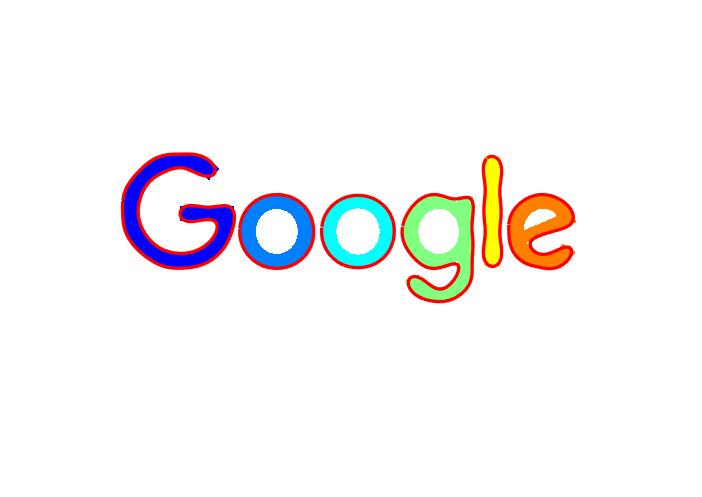

figure;
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for i = 1:length(B)
    boundary2 = B{i};
    z2 = fourier_transform(boundary2);
    perc2 = 5*length(z2)/100;
    s2 = fourier_inv_transform(z2, perc2);                                                        
    plot(s2(:,2), s2(:,1), 'r', 'LineWidth', 2);
end

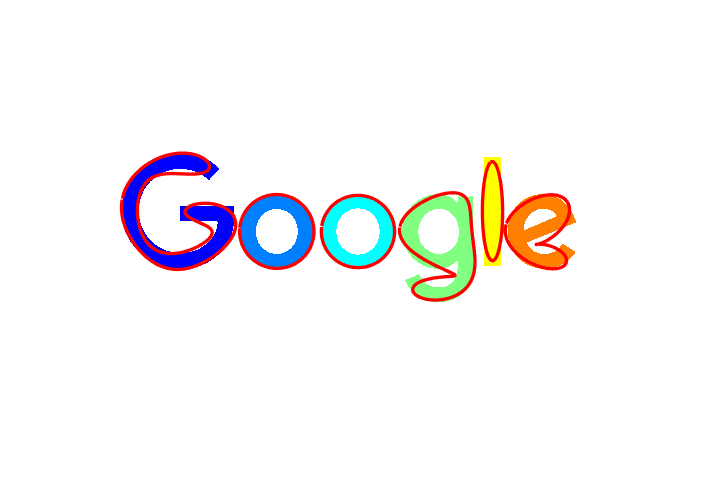

ans = 602

ans = 212

ans = 208

ans = 392

ans = 250

ans = 278

figure
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for i = 1:length(B)
    boundary3 = B{i};
    z3 = fourier_transform(boundary3);
    perc3 = 2*length(z3)/100;
    length(z3)
    s3 = fourier_inv_transform(z3, perc3);                                                        
    plot(s3(:,2), s3(:,1), 'r', 'LineWidth', 2);
end